data1 = readtable("sa7035.dat")

data1 = 81×2 table
     Var1       Var2  
    _______    _______

          1          0
    0.99815    0.00017
    0.99265    0.00079
    0.98367    0.00197
    0.97138    0.00375
      0.956    0.00615
    0.93777    0.00913
    0.91689    0.01264
    0.89359    0.01657
    0.86806    0.02082
    0.84049    0.02528
    0.81106    0.02984
    0.77993    0.03442
    0.74727    0.03894
    0.71326    0.04334
     0.6781     0.0476


x_loc = table2array(data1(:,"Var1"))

x_loc =     1.0000
    0.9981
    0.9927
    0.9837
    0.9714
    0.9560
    0.9378
    0.9169
    0.8936
    0.8681


y_loc = table2array(data1(:,"Var2"))

y_loc =          0
    0.0002
    0.0008
    0.0020
    0.0037
    0.0062
    0.0091
    0.0126
    0.0166
    0.0208


data2 = readtable("T2_Re0.278_M0.00_N9.0.xlsx")

data2 = 146×12 table
    alpha      CL        CD         CDp        Cm       TopXtr    BotXtr     Cpmin     Chinge    XCp    Var11    Var12 
    _____    ______    _______    _______    _______    ______    ______    _______    ______    ___    _____    ______

    -2.6     0.0214     0.0067    0.00155    -0.0627    0.7782    0.0052    -1.8911      0        0       0       3.211
    -2.5     0.0343    0.00688    0.00153    -0.0631    0.8003    0.0053    -1.7904      0        0       0      2.1046
    -2.4     0.0463    0.00703     0.0015    -0.0632    0.8092    0.0055     -1.691      0

Airfoil plot

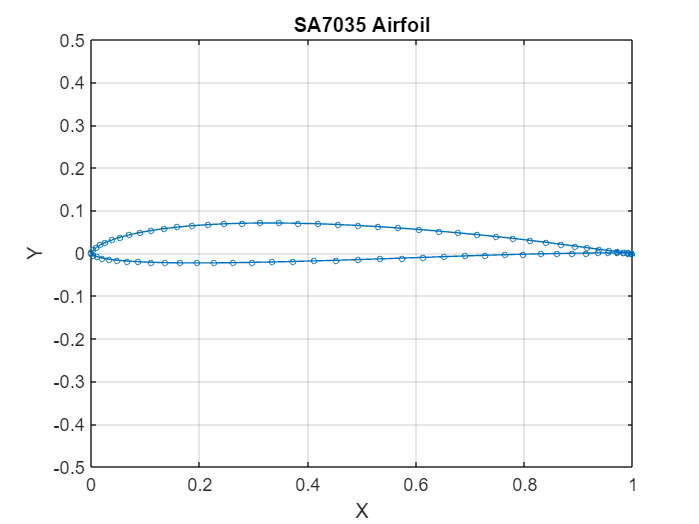

figure()
p = plot(x_loc,y_loc,'-o');
p.MarkerSize = 3;
xlim([0,1])
ylim([-0.5,0.5])
xlabel("X")
ylabel("Y")
title("SA7035 Airfoil")
grid on
saveas(gcf,'Airfoil.png')

alpha = table2array(data2(:,"alpha"))

alpha =    -2.6000
   -2.5000
   -2.4000
   -2.3000
   -2.2000
   -2.1000
   -2.0000
   -1.9000
   -1.8000
   -1.7000


C_L = table2array(data2(:,"CL"))

C_L =     0.0214
    0.0343
    0.0463
    0.0583
    0.0704
    0.0822
    0.0939
    0.1054
    0.1169
    0.1284


C_D = table2array(data2(:,"CD"))

C_D =     0.0067
    0.0069
    0.0070
    0.0071
    0.0072
    0.0073
    0.0074
    0.0074
    0.0075
    0.0075


C_Dp = table2array(data2(:,"CDp"))

C_Dp =     0.0015
    0.0015
    0.0015
    0.0015
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014
    0.0014


C_m = table2array(data2(:,"Cm"))

C_m =    -0.0627
   -0.0631
   -0.0632
   -0.0634
   -0.0635
   -0.0636
   -0.0637
   -0.0638
   -0.0639
   -0.0639


Xtr_top = table2array(data2(:,"TopXtr"))

Xtr_top =     0.7782
    0.8003
    0.8092
    0.8151
    0.8194
    0.8217
    0.8228
    0.8229
    0.8224
    0.8214


Xtr_bot = table2array(data2(:,"BotXtr"))

Xtr_bot =     0.0052
    0.0053
    0.0055
    0.0058
    0.0062
    0.0067
    0.0074
    0.0082
    0.0093
    0.0130


Min_Cp = table2array(data2(:,"Cpmin"))

Min_Cp =    -1.8911
   -1.7904
   -1.6910
   -1.5904
   -1.4890
   -1.3877
   -1.2859
   -1.1847
   -1.0889
   -1.0044


figure()
p2 = plot(alpha,C_L,Color='blue')

p2 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.6000 -2.5000 -2.4000 -2.3000 -2.2000 -2.1000 -2 -1.9000 -1.8000 -1.7000 -1.6000 -1.5000 -1.4000 -1.3000 -1.2000 -1.1000 -1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 … ] (1×146 double)
              YData: [0.0214 0.0343 0.0463 0.0583 0.0704 0.0822 0.0939 0.1054 0.1169 0.1284 0.1391 0.1498 0.1605 0.1712 0.1818 0.1924 0.2024 0.2103 0.2175 0.2263 0.2356 0.2445 0.2532 0.2622 0.2719 0.2838 0.2989 0.3166 0.3361 0.3555 … ] (1×146 double)

  Show <a href="matlab:if exist('p2', 'var'), matlab.graphics.internal.getForDisplay('p2', p2, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p2'), end">all properties</

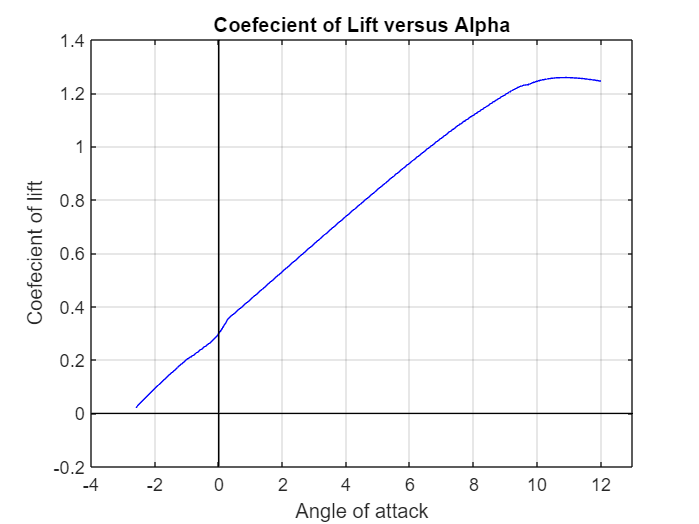

grid on 
ylim([-0.2,1.4])
xlim([-4,13])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("Angle of attack")
ylabel("Coefecient of lift")
title("Coefecient of Lift versus Alpha")
saveas(gcf,'Cl_alpha.png')

figure()
p3 = plot(alpha,C_D,Color='blue')

p3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-2.6000 -2.5000 -2.4000 -2.3000 -2.2000 -2.1000 -2 -1.9000 -1.8000 -1.7000 -1.6000 -1.5000 -1.4000 -1.3000 -1.2000 -1.1000 -1 -0.9000 -0.8000 -0.7000 -0.6000 -0.5000 -0.4000 -0.3000 -0.2000 -0.1000 0 0.1000 0.2000 … ] (1×146 double)
              YData: [0.0067 0.0069 0.0070 0.0071 0.0072 0.0073 0.0074 0.0074 0.0075 0.0075 0.0073 0.0072 0.0070 0.0069 0.0067 0.0066 0.0063 0.0057 0.0054 0.0053 0.0053 0.0053 0.0053 0.0053 0.0053 0.0054 0.0054 0.0055 0.0056 0.0056 … ] (1×146 double)

  Show <a href="matlab:if exist('p3', 'var'), matlab.graphics.internal.getForDisplay('p3', p3, 'matlab.graphics.chart.primitive.Line'), else, matlab.graphics.internal.getForDisplay('p3'), end">all properties</

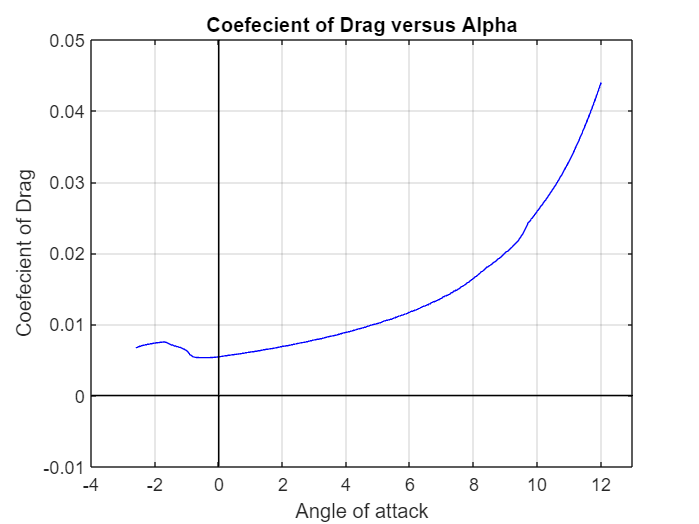

grid on 
ylim([-0.01,0.05])
xlim([-4,13])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("Angle of attack")
ylabel("Coefecient of Drag")
title("Coefecient of Drag versus Alpha")
saveas(gcf,'Cd_alpha.png')

figure()
p3 = plot(C_L,C_D,Color='blue')

p3 =   Line with properties:

              Color: [0 0 1]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0.0214 0.0343 0.0463 0.0583 0.0704 0.0822 0.0939 0.1054 0.1169 0.1284 0.1391 0.1498 0.1605 0.1712 0.1818 0.1924 0.2024 0.2103 0.2175 0.2263 0.2356 0.2445 0.2532 0.2622 0.2719 0.2838 0.2989 0.3166 0.3361 0.3555 … ] (1×146 double)
              YData: [0.0067 0.0069 0.0070 0.0071 0.0072 0.0073 0.0074 0.0074 0.0075 0.0075 0.0073 0.0072 0.0070 0.0069 0.0067 0.0066 0.0063 0.0057 0.0054 0.0053 0.0053 0.0053 0.0053 0.0053 0.0053 0.0054 0.0054 0.0055 0.0056 0.0056 … ] (1×146 double)

  Show all properties


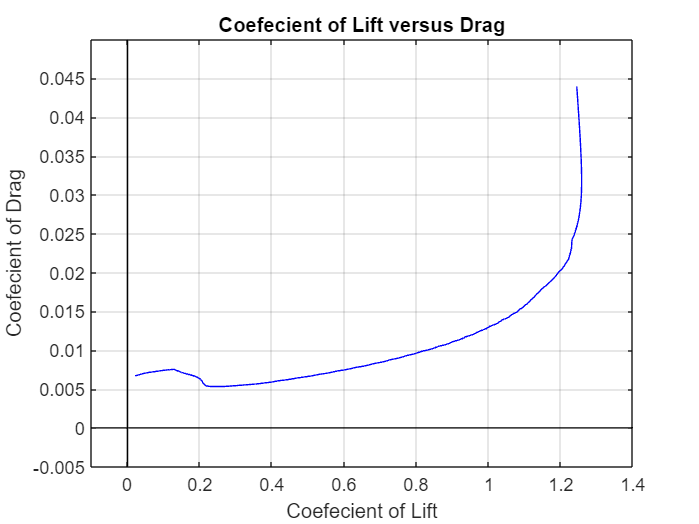

grid on 
ylim([-0.005,0.05])
xlim([-0.1,1.4])
xL = xlim;
yL = ylim;
line([0 0], yL,Color="black");  %x-axis
line(xL, [0 0],Color="black");  %y-axis
xlabel("Coefecient of Lift")
ylabel("Coefecient of Drag")
title("Coefecient of Lift versus Drag")
saveas(gcf,'Cl_Cd.png')